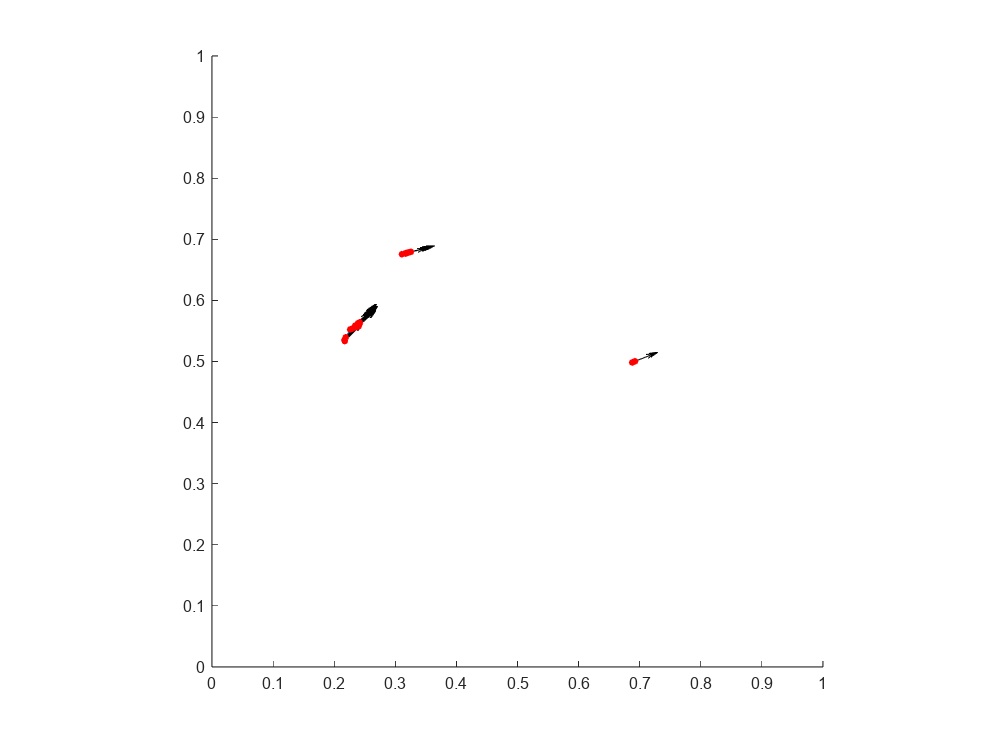

horizon = 100000; % time horizon of the simuation
dt = 0.01; % delta time

% Set up the figure and axis
figure('Position', [100 100 800 600]);
limit = 1;
axis([0 limit 0 limit]);
axis square;
hold on;

% Set up the region
x = linspace(0, limit, 100);
y = linspace(0, limit, 100);

% Initialize the boids
num_boids = 50;
[q, p] = generate_boids(num_boids, limit);
r = 0.5*limit/sqrt(num_boids); % the distance within which two boids are considered neighbours
max_vel = 1;
max_accel = 10;

% Update Loop
for i = 1:horizon
    
    neighbours = findNeighbours(q, q, r);
    for j = 1:num_boids
    
        neighbours_of_j = neighbours{j};
        % Find the force acting on the jth boid
        force_on_j = generate_force(q, p, j, neighbours_of_j);

        %-------------------------- actuator saturation -----------------
        if vecnorm(force_on_j, 2, 2) > max_accel
            force_on_j = (max_accel/vecnorm(force_on_j, 2, 2)) * force_on_j;
        end

        % ------------------------- velocity control --------------------
        % update velocity
        if vecnorm(p(j,:), 2, 2) > max_vel
            p(j,:) = (max_vel/vecnorm(p(j,:), 2, 2)) * p(j,:); % cap the velocity at max_vel
        else
            p(j,:) = [p(j,1) + force_on_j(1)*dt, p(j,2) + force_on_j(2)*dt];
        end

        % update position
        q(j,:) = mod(q(j,:) + p(j,:)*dt, limit); % wraps the boids to within the frame -- exits left, enters right

    end

    g = get_weighted_adjacency_matrix(q, r);
    s = sparse(g);
    scale = limit/25;
    % plots the velocity vectors and positions
    cla;
    gplot(s,q); 
    quiver([q(:,1)], [q(:,2)], scale*(p(:,1)./vecnorm(p,2,2)), scale*(p(:,2)./vecnorm(p,2,2)), 0, 'Color', 'k'); 
    plot(q(:,1), q(:,2), 'ro', 'MarkerSize', 3.5, 'MarkerFaceColor','red');

    % prints the ids of the boids
    % for k = 1:num_boids
    %     text(p(k,1), p(k,2), string(k));
    % end

    pause(0.01);
    
end

function out = generate_force(q, p, id, neighbour_ids)

    %-----------------------------------------------------------------
    function out = sigmaEpsilon(z, epsilon)
        out = z ./ sqrt(1 + epsilon*(vecnorm(z, 2, 2)));
    end

    function rho = bumpFunction(z, h)
        rho = zeros(size(z));
        rho(z >= 0 & z < h) = 1;
        rho(z >= h & z <= 1) = (1/2) * (1 + cos(pi * ((z(z >= h & z <= 1) - h)/(1 - h))));
    end

    function out = phi(z, a, b) 
        % merely scaling and shifting the sigmaEpsilon function
        c = abs(a-b)/sqrt(4*a*b);
        out = 0.5 * ((a+b) * sigmaEpsilon(z+c, 1) + (a-b));
    end

    function out  = phi_alpha(z, r_alpha, d_alpha, a, b)
        out = bumpFunction(z/r_alpha, 0.2) .* phi(z-d_alpha, a, b);
    end

    function out = sigmaNorm(z, epsilon)
        out = (1/epsilon) * (sqrt(1 + epsilon * vecnorm(z, 2, 2).^2) - 1);
    end
    %------------------------------------------------------------------

    if isempty(neighbour_ids)
        out = [0,0];
    else

        % q(id,:) -- position of the jth boid
        % q(neighbour_ids,:) -- positions of the neighbouring boids
        % p(id,:) -- velocity of the jth boid
        % p(neighbour_ids,:) -- velocities of the neighbouring boids
    
        % ---------------------- system params ---------------------------
        epsilon = 0.1;
        r = 8.4; % CHANGE THIS
        d = 7; % CHANGE THIS
        h = 0.2;
        kappa = r/d;

        gradient = 1;
        consensus = 0.05;
    
        % --------------------- transformed params -----------------------
        r_alpha = sigmaNorm(r, epsilon);
        d_alpha = sigmaNorm(d, epsilon);
        
        % --------------------- gradient term ----------------------------
        n_ij = sigmaEpsilon(q(neighbour_ids,:) - q(id,:), epsilon);
        % u_grad = -sum(phi_alpha(sigmaNorm(q(neighbour_ids,:) - q(id,:), epsilon), r_alpha, d_alpha, 10, 20) .* n_ij, 1);
        u_grad = -sum(phi_alpha(sigmaNorm(q(neighbour_ids,:) - q(id,:), epsilon), r, d, 100, 100) .* n_ij, 1);

        % --------------------- consensus term ---------------------------
        % a_ij = bumpFunction(sigmaNorm((q(neighbour_ids,:) - q(id,:)/r_alpha), epsilon), h);
        a_ij = bumpFunction(sigmaNorm((q(neighbour_ids,:) - q(id,:)/r), epsilon), h);
        u_cons = sum(a_ij .* p(neighbour_ids,:) - p(id,:), 1);
    
        %------------------------------------------------------------------
    
        out = gradient*u_grad + consensus*u_cons;
    
        % set NaN values to zero, else the boid disappears
        out(isnan(out)) = 0;
    end
end

function neighbors = findNeighbours(boids, all_boids, range)
    neighbors = rangesearch(all_boids, boids, range);
    neighbors = cellfun(@(a) a(2:end), neighbors, 'UniformOutput', false);
end

function out = get_unweighted_adjacency_matrix(points, range)

    function out = cell2logic(c, n)
    out = zeros(1, n);
    out(c) = 1;
    end

    neighbours = findNeighbours(points, points, range);
    out = cell2mat(cellfun(@(a) cell2logic(a, size(points, 1)),  neighbours, 'UniformOutput', false));
end

function out = get_weighted_adjacency_matrix(points, range)

    distances = pdist2(points, points);
    out = get_unweighted_adjacency_matrix(points, range) .* distances;

end